# Algoritmos Numéricos por Computadora

# Tercer parcial - Primavera 2020

Cambia el nombre del script a Nombre (ej: Marcelo).

Sube tu archivo resultado a comunidad $\to$ Tercer parcial antes de las 11:55 pm del viernes 1 de mayo.

- **Cuando yo pruebe tu script deben desplegarse en la pantalla todos los resultados. **

- **Debes escribir al final del script todas las funciones que uses.**

- **El examen es individual, debes resolverlo sin ayuda de ninguna persona. **

- **Revisa con mucho cuidado tus respuestas. El examen será calificado de manera muy estricta.**

## 1. Resuelve la siguiente ecuación diferencial de primer orden


$$\frac{\mathrm{d}}{\mathrm{d}x}y+\frac{2}{x}y=\frac{e^{x^2 } }{x}$$


### a) Usa el método del factor de integración. Escribe aquí todos los pasos de tu solución. Puedes insertar ecuaciones desde Matlab o pegar una imagen con tus cálculos.

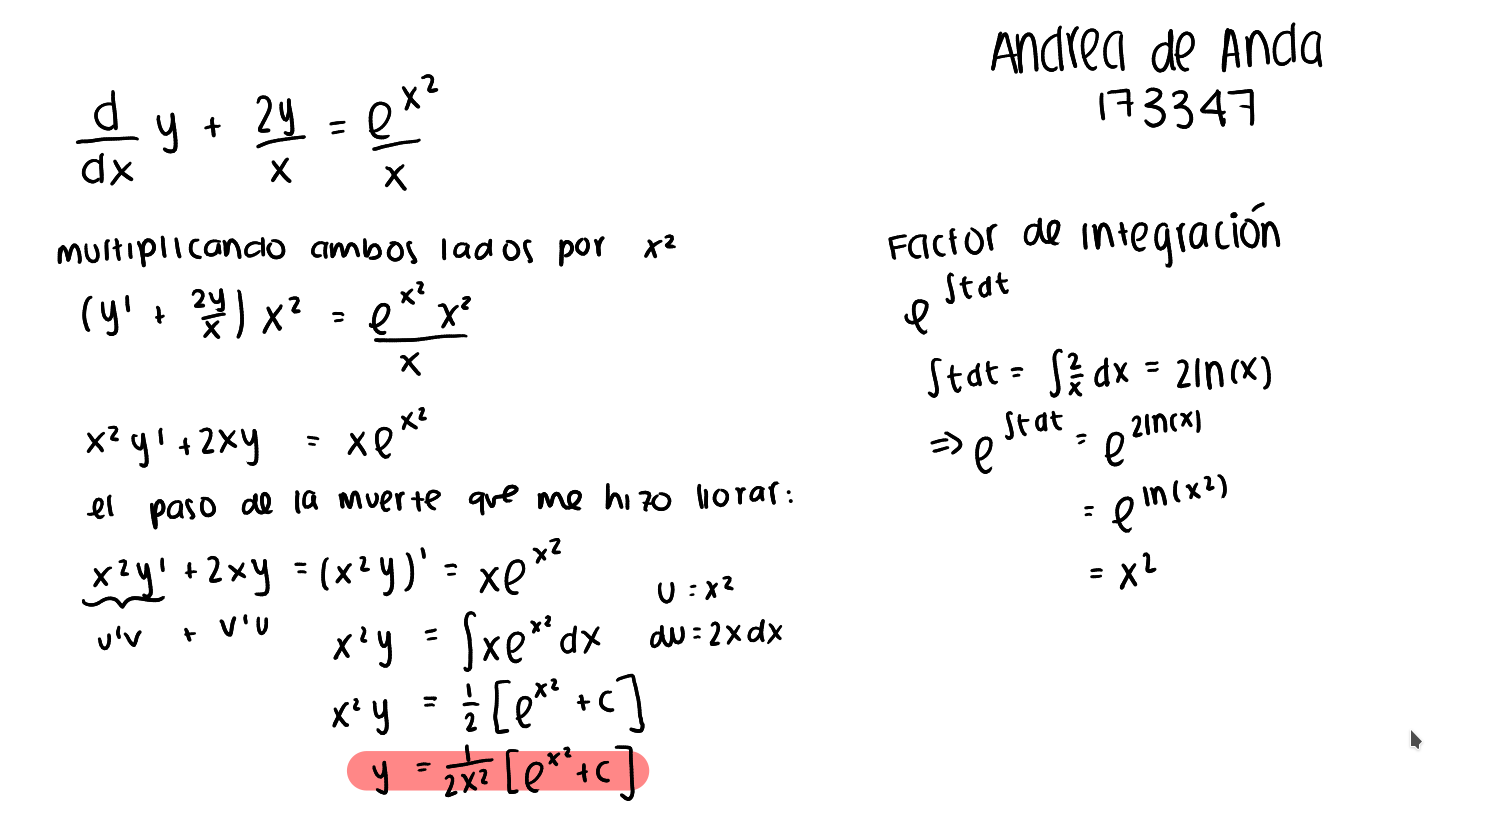

### b) Usa el cálculo simbólico de Matlab

syms y(x) 
eqn = diff(y,x) == exp(x^2)/x-(2/x)*y

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\frac{{\mathrm{e}}^{x^{2}}}{x}-\frac{2\,y\left(x\right)}{x}$$

yG = dsolve(eqn)

$$yG = \frac{{\mathrm{e}}^{x^{2}}}{2\,x^{2}}+\frac{C_{1}}{x^{2}}$$

## 2. Resuelve la siguiente ecuación diferencial de primer orden


$$x\;\textrm{dx}+y\;\textrm{dy}=0$$
       

### a) Usa el método de la diferencial exacta. Escribe aquí todos los pasos de tu solución.  Puedes insertar ecuaciones desde Matlab o pegar una imagen con tus cálculos.

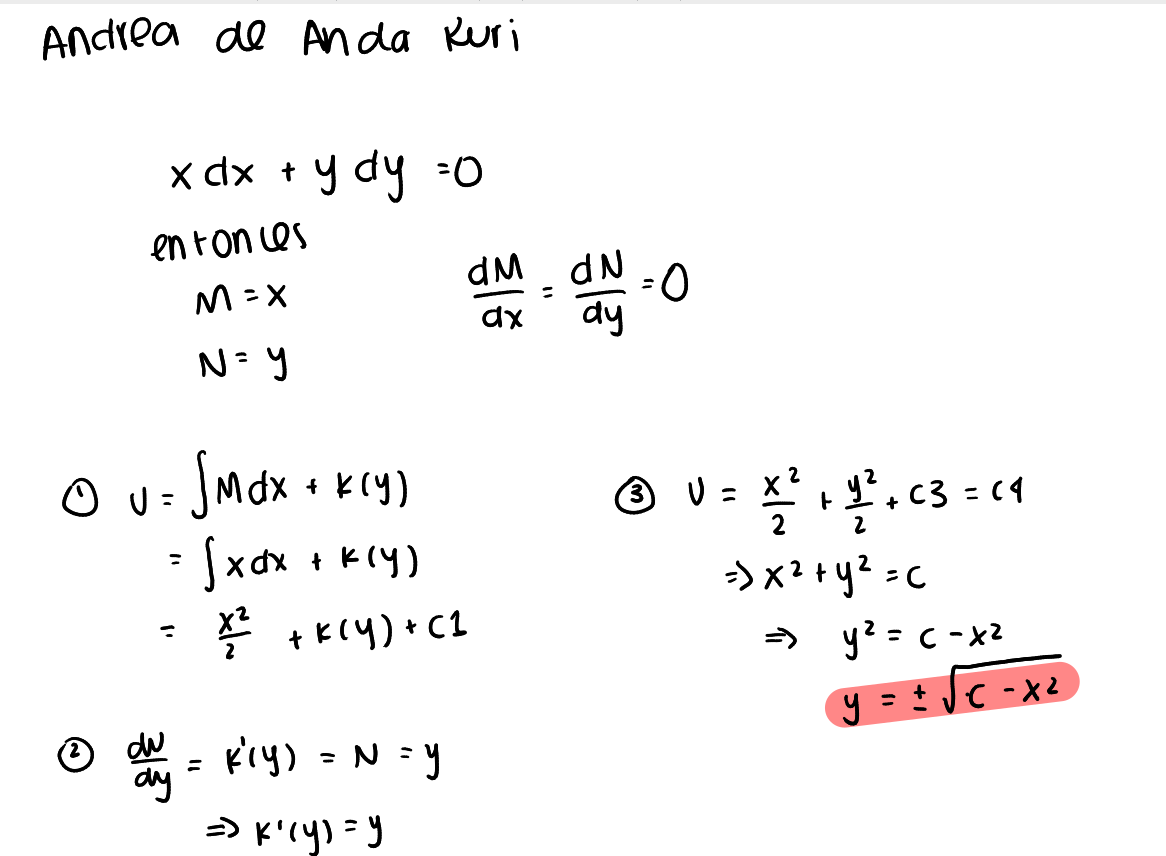

### b) Usa el cálculo simbólico de Matlab

syms y(x) 
eqn = diff(y,x) == -x/y

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{x}{y\left(x\right)}$$

ySolve = dsolve(eqn)

$$ySolve = \left(\begin{array}{c} \sqrt{C_{1}-x^{2}}\\ -\sqrt{C_{1}-x^{2}} \end{array}\right)$$

## 3. Resuelve numéricamente el siguiente sistema de ecuaciones diferenciales de primer orden. Puedes usar cualquier método.


$$y^{\prime } =-2y+5e^{-t}$$
           
$$y\left(0\right)=2$$



$$z^{\prime } =-\frac{yz^2 }{2}$$
                     
$$z\left(0\right)=4$$


Grafica la solución entre t=0 y t=0.4. Agrega a la gráfica un título, etiquetas a los ejes y leyendas (adecuadas).

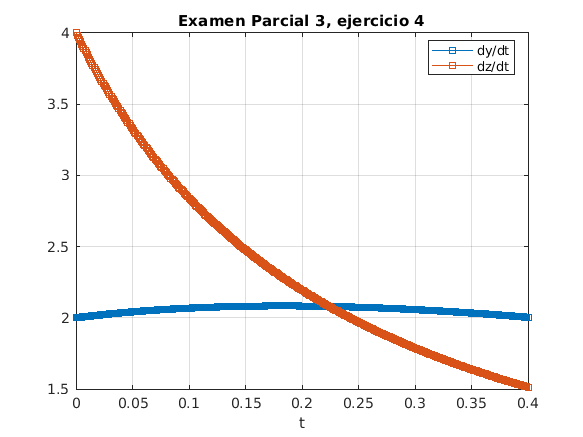

% y' = -2*y1+5*exp(-t)         y1(0) = 2
% z' = -(y1*y2^2)/2            y2(0) = 4
f=@(t,y) [-2*y(1)+5*exp(-t);(-y(1)*y(2)^2)/2];
y0=[2;4];
t0=0;
tf=0.4;
[t,y]=odeRK4bis(f,y0,t0,tf,0.001);
plot(t,y,'-s')
xlabel('t')
legend('dy/dt','dz/dt','location','best')
title('Examen Parcial 3, ejercicio 4')
grid on

## 4. Resuelve numéricamente la siguiente ecuación diferencial de segundo orden. Puedes usar cualquier método.

Se trata del oscilador de van der Pol (con amortiguamiento no lineal)


$$\frac{d^2 }{\mathrm{d}t^2 }y-\left(1-y^2 \right)\frac{\mathrm{d}}{\mathrm{d}t}y+y=0$$
          
$$y\left(0\right)=y^{\prime } \left(0\right)=1$$


Grafica la solución entre t=0 y t=10. Agrega a la gráfica un título, etiquetas a los ejes y leyendas (adecuadas).

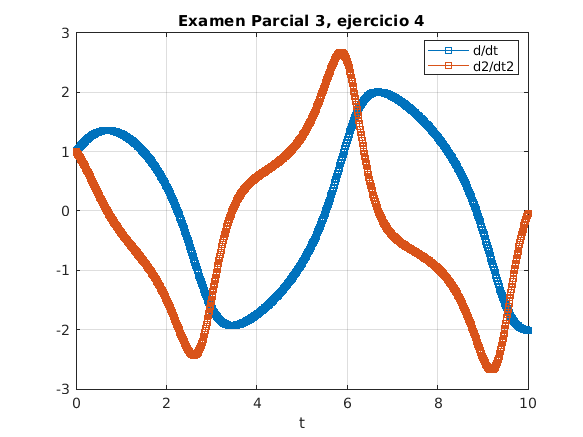

%vamos a pensar en la segunda derivada como si fuera una z
%y'=z                y=y(1)
%z'=(1-y^2)*z-y      z=y(2)
f=@(t,y) [y(2);(1-y(1)^2)*y(2)-y(1) ];
y0=[1;1];
t0=0;
tf=10;
[t,y]=odeRK4bis(f,y0,t0,tf,0.01);
plot(t,y,'-s')
xlabel('t')
legend('d/dt','d2/dt2','location','best')
title('Examen Parcial 3, ejercicio 4')
grid on

## 5. ¿Cuántos millones de personas habrá en 2022?

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. 

a) Resuelve la ecuación diferencial para calcular la población mundial *p* entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

b) ¿Cuántos millones de personas habrá en 2022?

c) Compara las respuestas obtenidas con los métodos de Heun y Heun iterativo, considerando que h=5.

syms y(t) 
kgm=0.026;
ymax=12000;
eqn = diff(y,t) == kgm*(1-(y/ymax))*y;
yG = dsolve(eqn);
yGs = simplify(yG);
cond = y(1950) == 2555;
yP = dsolve(eqn,cond) 

$$yP = \frac{12000}{{\mathrm{e}}^{\log\left(\frac{1889}{511}\right)-\frac{13\,t}{500}+\frac{507}{10}}+1}$$

yPs = simplify(yP)

$$yPs = \frac{6132000}{1889\,{\mathrm{e}}^{\frac{507}{10}-\frac{13\,t}{500}}+511}$$

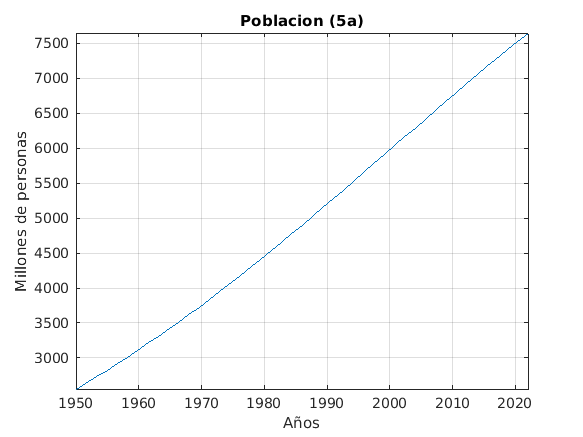


fplot(yPs, [1950 2022]);
grid on
title('Poblacion (5a)')
xlabel('Años');
ylabel('Millones de personas');

vpa(subs(yPs, t, 2022)) %Personas en 2022

$$ans = 7650.1023831563598422345820077763$$

f=@(t,y) kgm*(1-(y/ymax))*y;
y0=2555;
h=5;
t0=1950;
tf=2022;
[~,y1]=odeHeun(f,y0,t0,tf,h)

y1 = 	1.0e+03 *

    2.5550    2.8258    3.1159    3.4247    3.7511    4.0939    4.4511    4.8205    5.1995    5.5851    5.9741    6.3634    6.7496    7.1296    7.5004


[t,y2]=odeHeunIterativo(f,y0,t0,tf,h)

t =         1950        1955        1960        1965        1970        1975        1980        1985        1990        1995        2000        2005        2010        2015        2020


y2 = 	1.0e+03 *

    2.5550    2.8262    3.1166    3.4256    3.7524    4.0953    4.4527    4.8222    5.2013    5.5869    5.9760    6.3652    6.7515    7.1315    7.5023


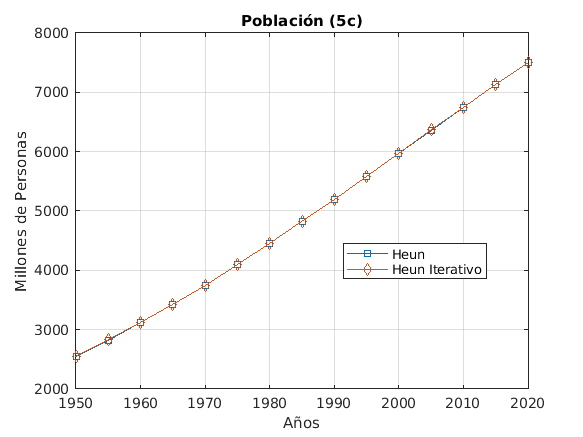

%Aunque arriba podemos ver que los valores de y1 y y2 son diferentes, no
%cambian tanto como para que se logren ver las dos lineas en la grafica.
plot(t, y1,'-s')
hold on
plot(t, y2, '-d')
xlabel('Años')
ylabel('Millones de Personas')
legend('Heun','Heun Iterativo','location','best')
hold off
title('Población (5c)')
grid on

## 6. Sistema masas - resortes con fricción

En el sistema de dos masas y tres resortes visto en clase, existe ahora adicionalmente una fuerza de fricción sobre cada masa $F_i =-b\frac{\mathrm{d}}{\mathrm{d}t}x_i \;$. Considera que $b=0\ldotp 0125$ y resuelve el sistema amortiguado. Usa los mismos valores que vimos en clase para las masas y los resortes. Considera la condición inicial x(0)=[0.025; 0.025] y v=[0; 0]. 

a) Grafica las posiciones de las dos masas. Agrega a la gráfica un título, etiquetas a los ejes y leyendas (adecuadas).

b) Encuentra de manera exacta el periodo de oscilación y la constante de decaimiento de la envolvente exponencial negativa. 

c) Grafica la energía total del sistema. Agrega a la gráfica un título, etiquetas a los ejes y leyendas (adecuadas).

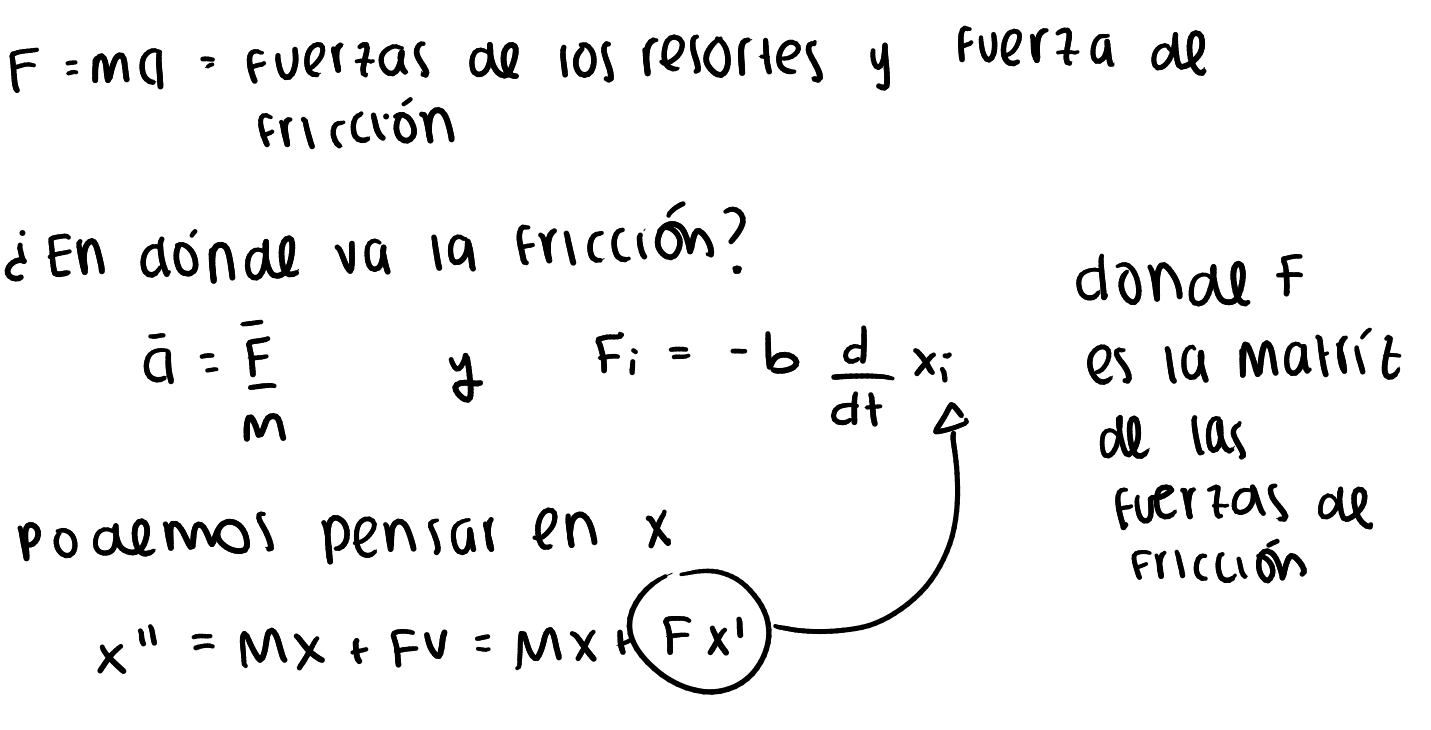

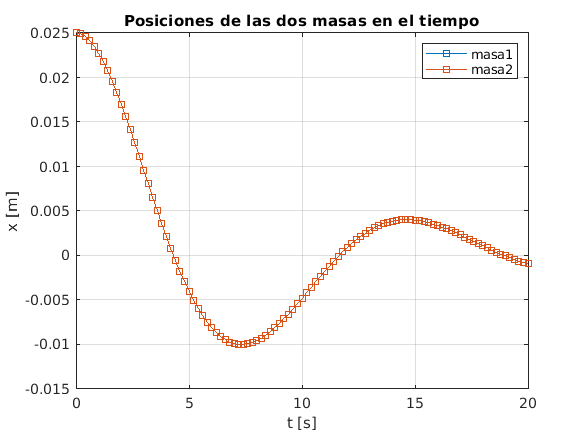

m = 0.05*ones(2,1);         % masas [kg]
k = 0.01*ones(3,1);         % constantes de los resortes
b=0.0125;
M = [-(k(1)+k(2))/m(1), k(2)/m(1);
    k(2)/m(2), -(k(2)+k(3))/m(2)];
F=[-b/m(1),0; 0,-b/m(2)];
Md = [zeros(2,2), eye(2); M, F];

f = @(t,xv) Md*xv;

TS = 20;     % Tiempo que dura la simulación ([s])
N = 100;     % Número de pasos
h = TS/N;    % Tamaño del paso 

% Condiciones iniciales x1=-x2 o x1=x2; velocidades iniciales = 0
x0 = 0.025;
xv0 = [x0;x0;0;0];
[t,xv] = odeRK4bis(f, xv0, 0, TS, h);
x = xv(1:2,:);
v = xv(3:4,:);
plot(t,x, '-s');
title('Posiciones de las dos masas en el tiempo')
legend('masa1','masa2')
xlabel('t [s]')
ylabel('x [m]')
grid on;

[V,D] = eig(Md);   
lambda = diag(D);   
% alfa^2 = lambda
alfa = sqrt(lambda);       % números imaginarios ( real(alfa) = [0;0] )
w = imag(alfa);            % angular frequency ([radianes/s])                         
T = (2*pi)./w              % two modes of oscillation, period [s    

T =     9.3685
   -9.3685
   11.7467
  -11.7467


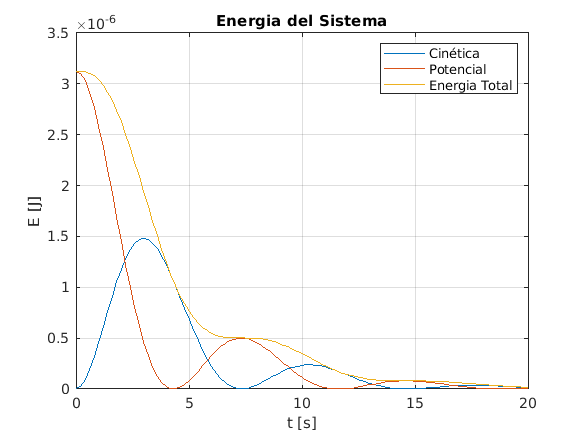

% energiacinetica=0.5*m*v^2
% energiapotencial=0.5*k*x^2

%usamos las mismas de la matriz M
K = [(k(1)-k(2)), k(2);
    k(2), (k(2)-k(3))];

ek=0.5*m.*v.^2;
ep=0.5*K*x.^2;
et=ek+ep;

plot(t,ek(1,:))
hold on
plot(t,ep(1,:))
plot(t,et(1,:))
title('Energia del Sistema')
legend('Cinética','Potencial','Energia Total')
xlabel('t [s]')
ylabel('E [J]')
grid on;
hold off

function [t,y] =odeRK4bis(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

function [t,y] = odeHeun(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(1,n);
    y(1)=y0;
    for i=1:1:n-1
        k1=f(t(i),y(i)); 
        yp=y(i)+h*k1; %predictor
        k2=f(t(i)+h,yp); 
        phi=(k1+k2)/2;
        y(i+1)=y(i)+phi*h;
    end    
end

function [t,y] = odeHeunIterativo(f,y0,t0,tf,h)
    MAX=100;
    tol=eps;
    t=t0:h:tf;
    n=length(t);
    y=zeros(1,n);
    y(1)=y0;
    for i=1:1:n-1
        y(i+1)=y(i)+f(t(i),y(i)*h);
        j=0;
        cond=true;
        while cond
            yp=y(i+1);
            y(i+1)=y(i)+0.5*(f(t(i),y(i))+f(t(i+1),y(i+1)))*h;
            j=j+1;
            cond = abs(y(i+1)-yp) > tol*abs(y(i+1)) && j<MAX;
        end
    end    
end